clear;
clc;
ts = 0.0001;
Fs = 1/ts;
t0 = 0.1;
f_delta = 100; %f_delta = k_f
fc = 250;

# **CA2-Q1-810101429**

#### ***A:***

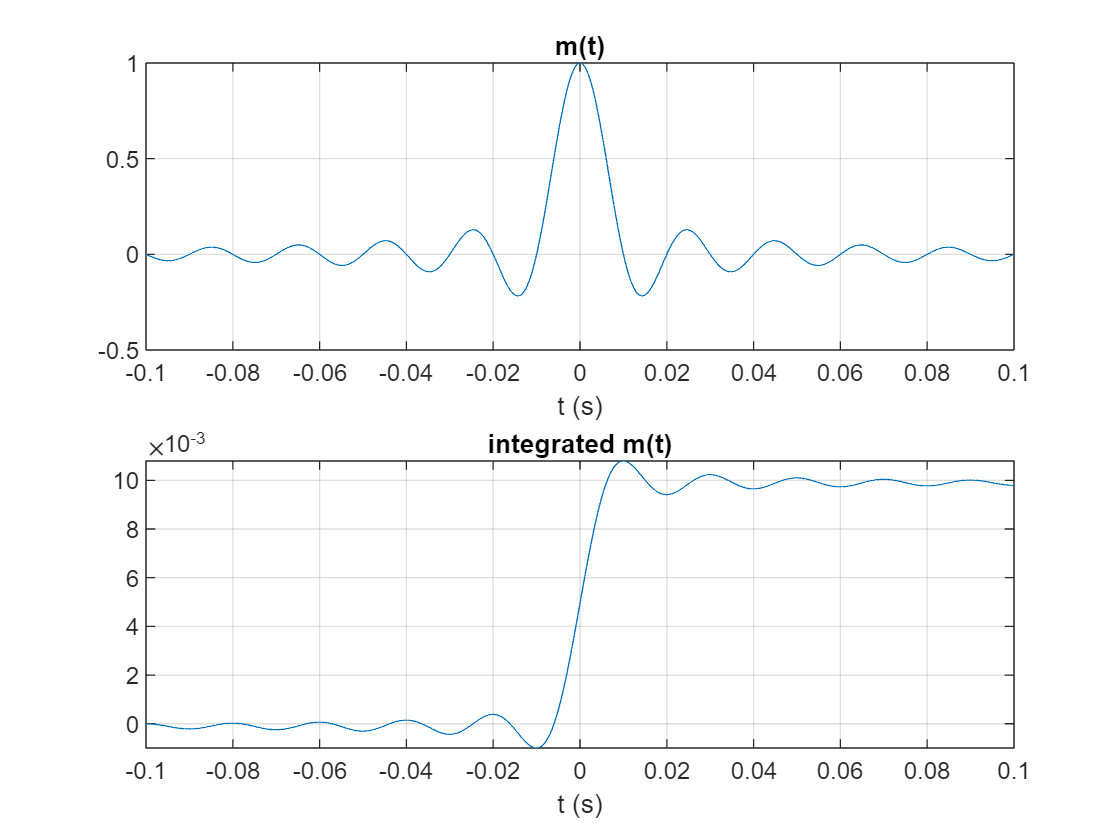

time_vector = -t0:ts:t0;
input = sinc(100 * time_vector);

integrated_input = cumsum(input)*ts;

figure;
subplot(2,1,1);
plot(time_vector, input);
xlabel('t (s)');
title('m(t)');
grid on;
subplot(2,1,2);
plot(time_vector, integrated_input);
xlabel('t (s)');
title('integrated m(t)');
grid on;

#### ***B:***

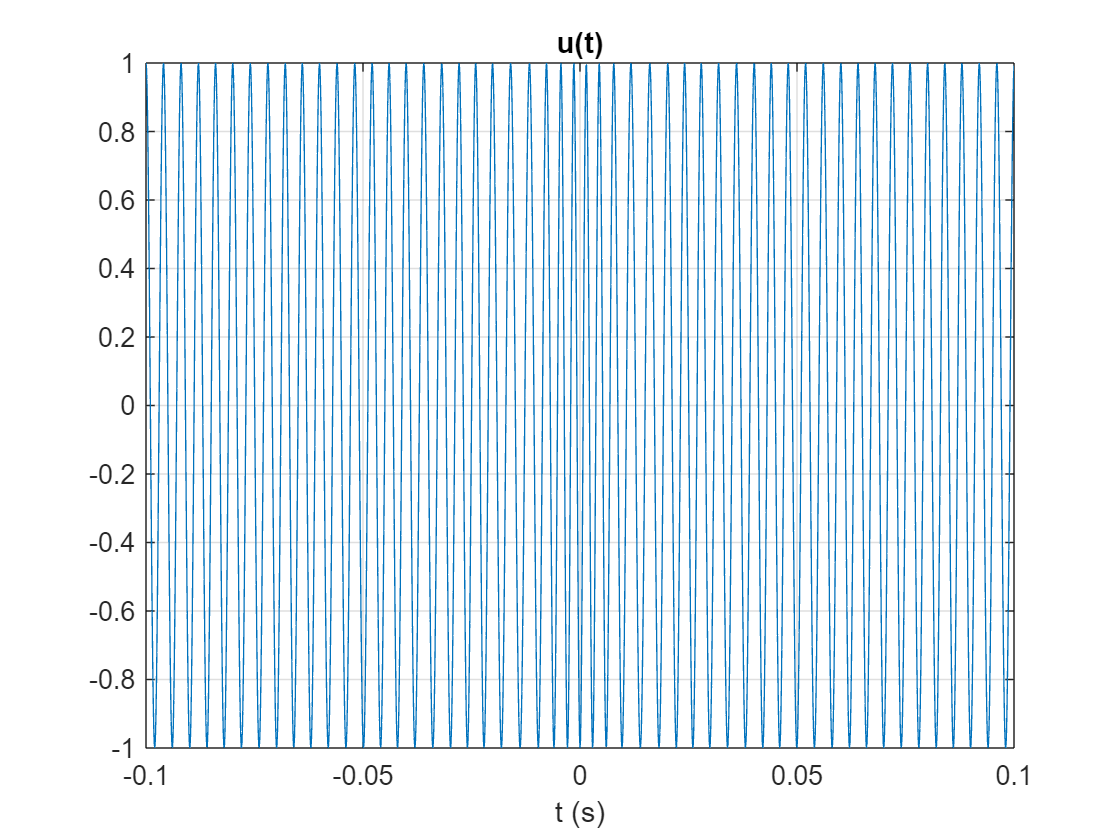

FM_modulated_signal = FM(integrated_input, time_vector, f_delta);

figure;
plot(time_vector, FM_modulated_signal);
xlabel('t (s)');
title('u(t)');
grid on;

#### ***C:***

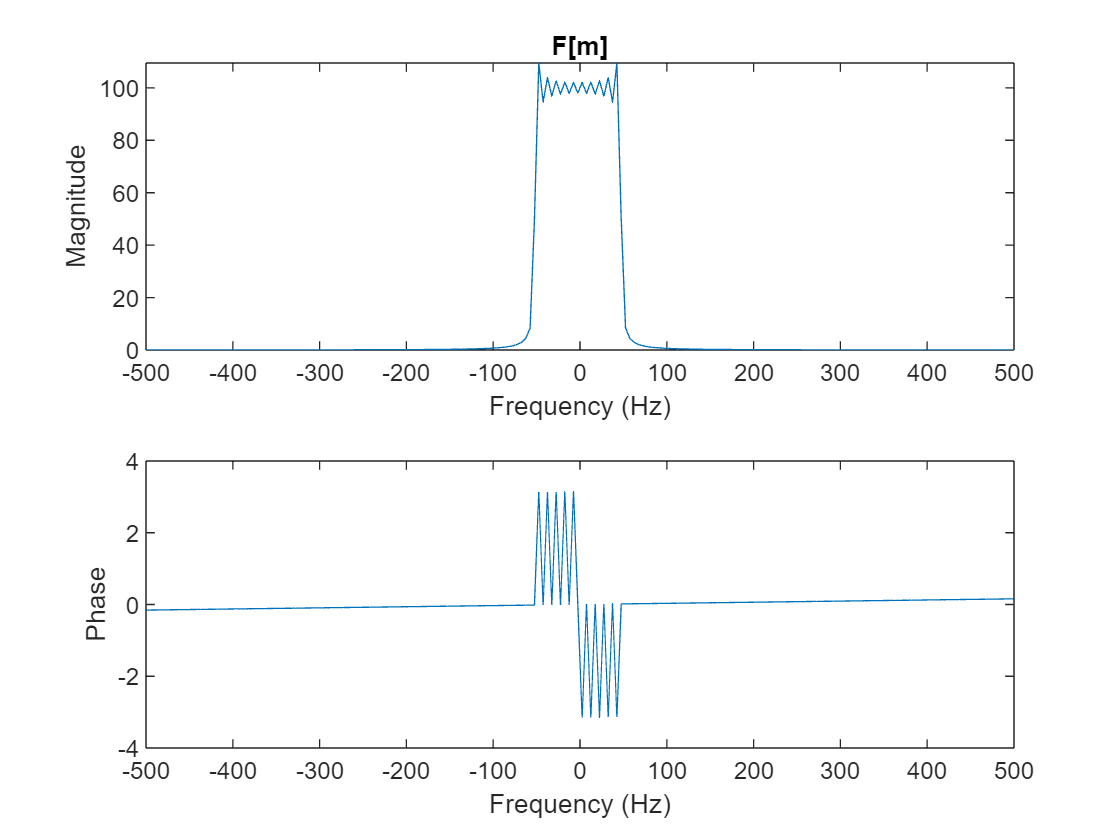

F_m = fftshift(fft(input));
n = length(input);
f = (-n/2:n/2-1)*(Fs/n);

figure;
subplot(2,1,1);
plot(f,abs(F_m));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([-500 500]);
title('F[m]');
subplot(2,1,2);
plot(f,angle(F_m));
xlabel('Frequency (Hz)');
ylabel('Phase');
xlim([-500 500]);

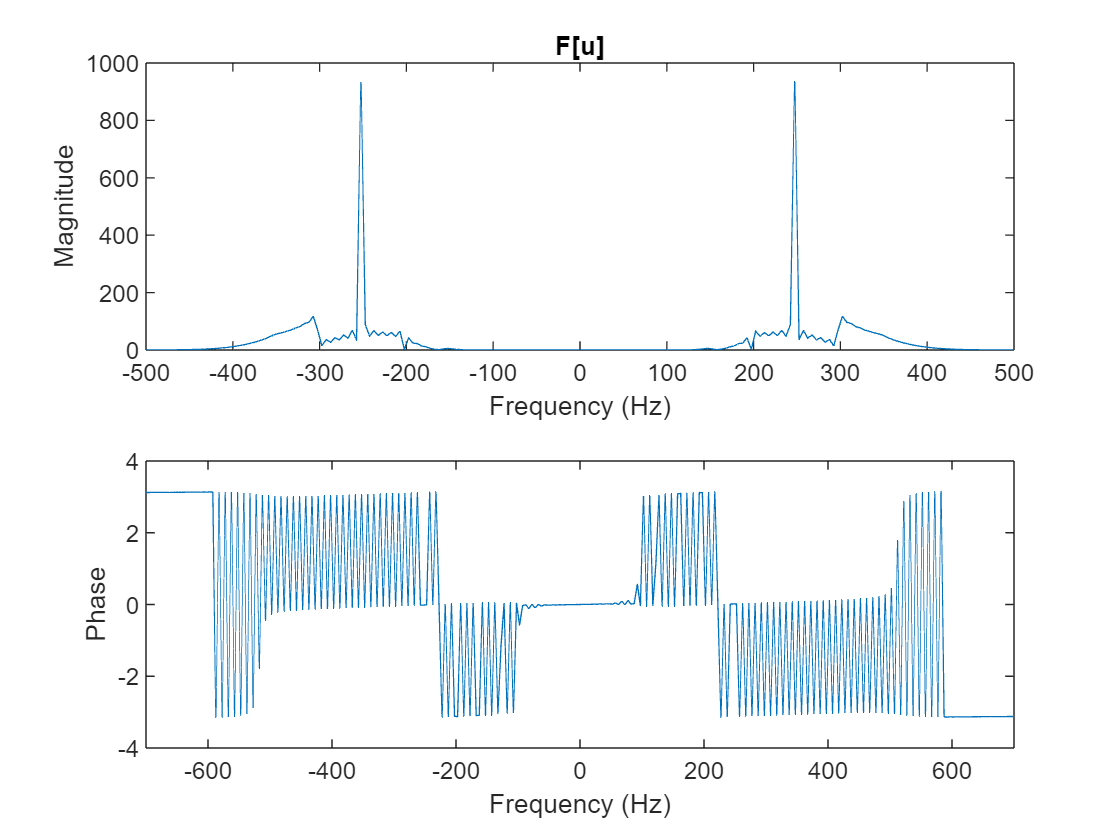


F_u = fftshift(fft(FM_modulated_signal));

figure;
subplot(2,1,1);
plot(f,abs(F_u));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[u]');
xlim([-500 500]);
subplot(2,1,2);
plot(f,angle(F_u));
xlabel('Frequency (Hz)');
ylabel('Phase');
xlim([-700 700]);

#### ***D:***

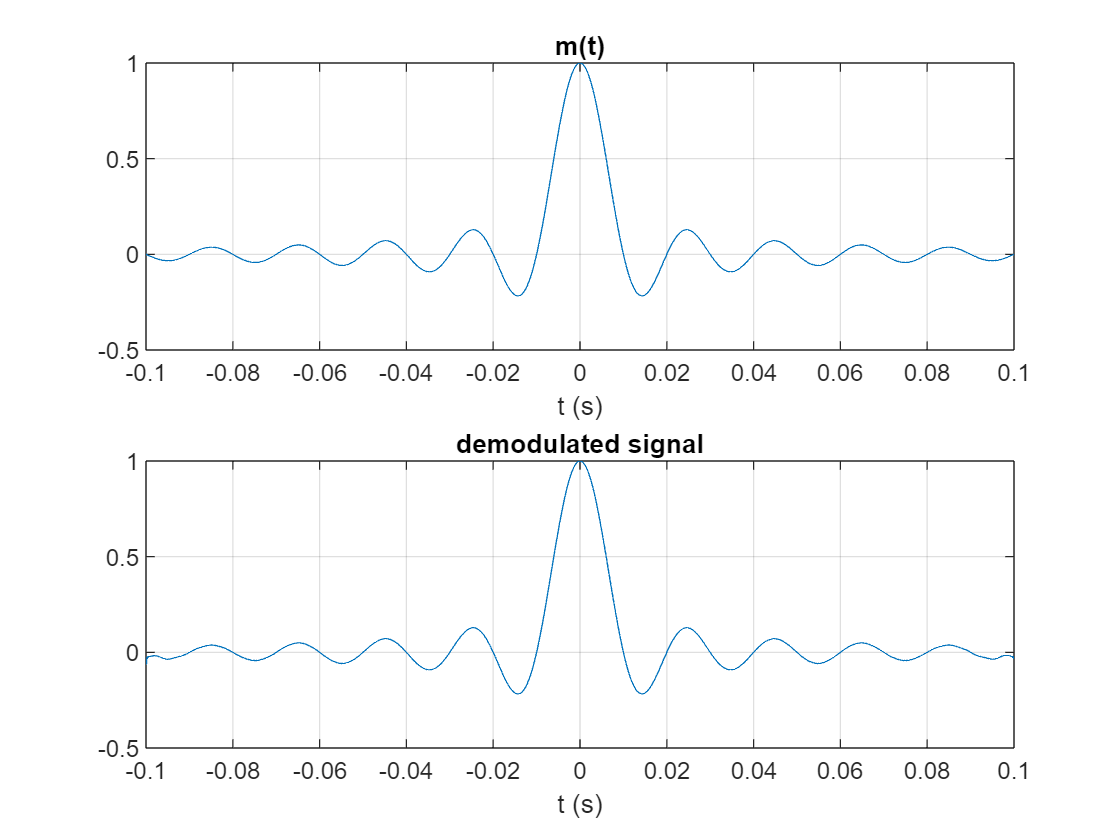

analytic_signal = hilbert(FM_modulated_signal);
phase = unwrap(angle(analytic_signal));
m_phase = phase - 2*pi*fc*time_vector;

phase_diff = diff(m_phase);

demodulated_signal = phase_diff * Fs/ (2*pi*f_delta);

figure;
subplot(2,1,1);
plot(time_vector, input);
xlabel('t (s)');                                                                                                                                                                               
title('m(t)');
grid on;
subplot(2,1,2);
plot(time_vector(2:end), demodulated_signal);
xlabel('t (s)');
title('demodulated signal');
grid on;

***FM modulating function:***

function FM_modulated = FM (integrated_input, time_domain, f_delta)
    fc = 250; %% modulating frequency
    FM_modulated = cos(2*pi*fc*time_domain + 2*pi*f_delta*integrated_input);
end